%loading some data
clear
load('Data\Calibrated_Airfoil_Pressure_Pa_Interpolated_Coeffs.mat')
load('Data\calibrated_manometer_data_Pa.mat')
load('Code\location.mat')
velocity = importdata('Data/velocities_manometer.csv')

velocity =    35.5008   34.8833   36.1844   35.5981   36.2791   36.1813   35.8883   36.0871   36.8536   36.5693   35.7921
    0.7096    0.7006    0.7222    0.7115    0.7242    0.7225    0.7173    0.7205    0.7349    0.7294    0.7153


load('Data\autocorrelation_error_deltaP.mat')

gif = 'Data\C_p Graphs\Animated.gif';

%setting constant values
q = 1/2 * 1.225 * velocity(1,:).^2;
delta_u = velocity(2,:)

delta_u =     0.7096    0.7006    0.7222    0.7115    0.7242    0.7225    0.7173    0.7205    0.7349    0.7294    0.7153


p = [p0; p3; p6; p8; 
     p10; p11; p13; p15;
     p16; p17; p20];
idx = [0, 3, 6, 8, 10, 11, 13, 15, 16, 17, 20];
formatspec = 'XFOIL Analysis/clark_y_%d.cp';

delta_Cp = zeros(11, 19);

delta_Cp =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0   

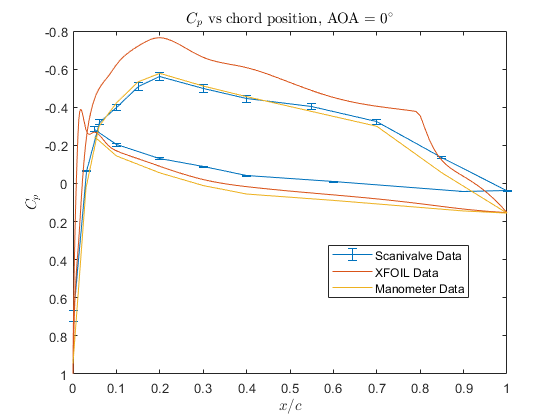

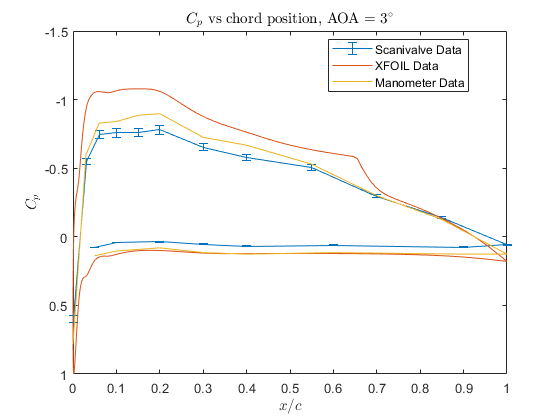

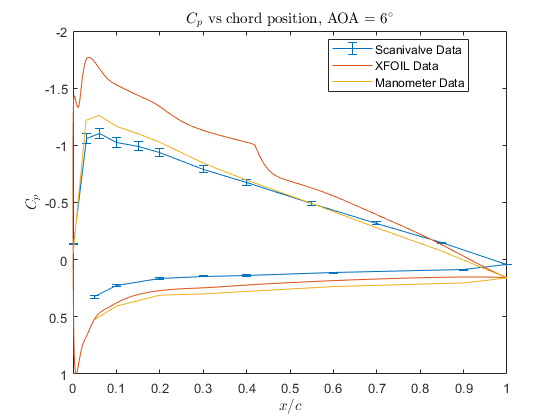

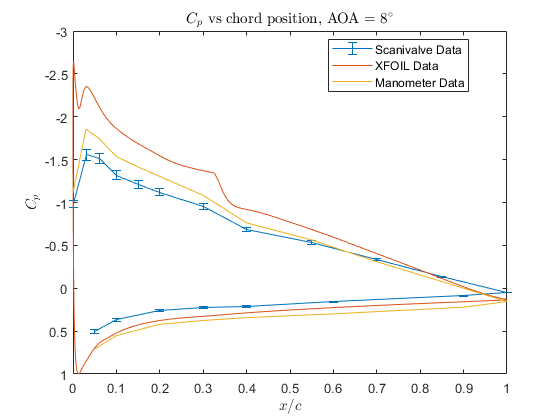

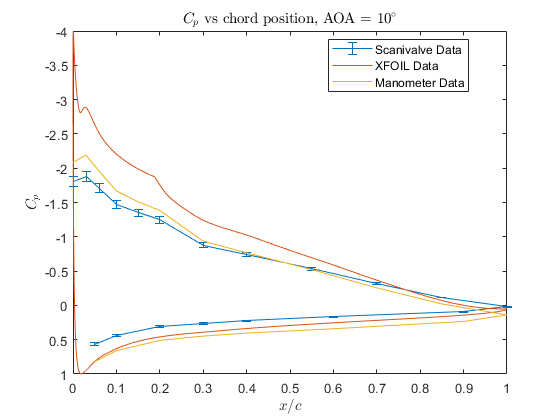

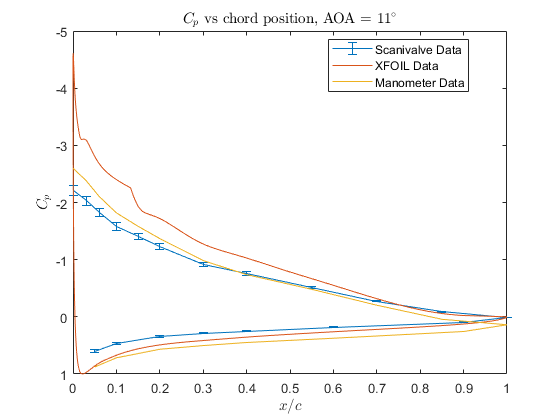

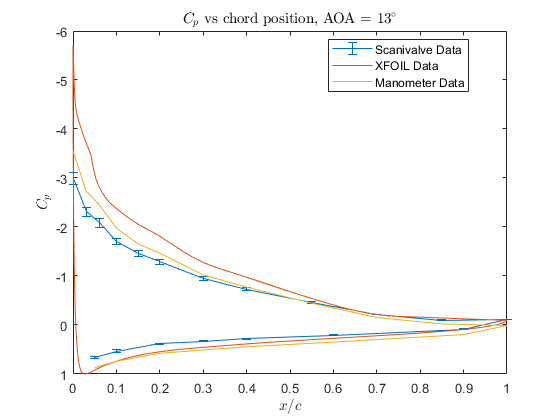

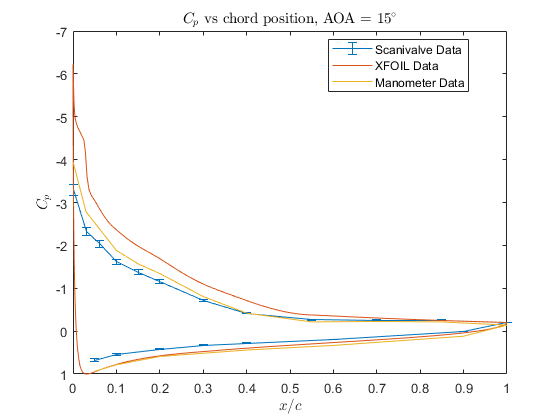

for i = 1:11
    %Plot Scanivalve Data
    h = figure;
    
    
    %error caluclation
    delta_dp = 115*err(i,1);
    delta_q = 2 * q(1,i)/velocity(1,i) * velocity(2,i);
    err_dp = 1/q(1,i) * delta_dp;
    err_q = p(i, :)/(q(1,i)^2) * delta_q;
    
    delta_Cp(i,:) = sqrt(err_dp^2 ...
                    +(err_q).^2);
    
    errorbar(location, p(i, :)/q(1,i), delta_Cp(i,:));
    
    %Plot XFOIL Data
    filename = sprintf(formatspec, idx(1,i));
    A = importdata(filename,' ', 3);
    hold on
    plot(A.data(:,1), A.data(:, 3))
    %Plot Manometer Data acquired from Mingde
    plot(location, airfoil_manometer(i, :)/q(1,i))
    hold off
    
    %Setting a reversed graph and adding labels
    set(gca, 'YDir','reverse')
    xlim([0 1])
    xlabel('$x/c$', "interpreter", "latex")
    ylabel('$C_p$',"interpreter",'latex')
    title(strcat(sprintf('$C_p$ vs chord position, AOA = %d', idx(1, i)), '$^\circ$'), 'interpreter', 'latex')
    legend('Scanivalve Data', 'XFOIL Data','Manometer Data','location',"best")
    
    
    saveas(h, sprintf('Data/C_p Graphs/AOA%d.png', idx(1,i)))
    %Creating a gif for fun
    frame = getframe(h); 
    im = frame2im(frame); 
    [imind,cm] = rgb2ind(im,256);
    
    if i == 1
        imwrite(imind,cm,gif,'gif', 'Loopcount',inf);  
    else 
        imwrite(imind,cm,gif,'gif','WriteMode','append'); 
    end
    
end